# Cleaning Workspace

clear;
close all;
clc;

# Initialization Parameters

## Massive MIMO Parameters

Parameters of a Massive MIMO systems with $$M$$-antennas base station, $K$ single-antenna user terminals, and $N$multipaths.

M = 500;                                                             % Number of Antennas
K = 2;                                                               % Number of Users
N = 50;                                                              % Number of Multipaths

m = (0:M-1).';

## Cell Parameters

Parameters of an hexagonal cell with interfering objects

R = 500;                                                             % Cell's raidus (circumradius) in meters
r = sqrt(3)/2*R;                                                     % Cell's inradius in meters

x_cell = [R R/2 -R/2 -R -R/2 R/2 R]';                                % Cell's x-coordinates
y_cell = [0 r    r    0 -r  -r   0]';                                % Cell's y-coordinates

% x_cell = [0 r    r    0 -r  -r   0]';                                % Cell's x-coordinates
% y_cell = [R R/2 -R/2 -R -R/2 R/2 R]';                                % Cell's y-coordinates 

H_bs = 30;                                                           % Height of base station in meters

H_user_min = 1.50;                                                   % Minimum height of user terminals in meters
H_user_max = 2.20;                                                   % Maximum height of user terminals in meters

H_user = H_user_min + (H_user_max - H_user_min)*rand(K,1);           % Height of user terminals in meters

H_object_min = H_user_max;                                           % Minimum height of interfering objects in meters
H_object_max = H_bs;                                                 % Maximum height of interfering objects in meters

H_object = H_object_min + (H_object_max - H_object_min)*rand(N,1);   % Height of interfering objects in meters

## Propagation Parameters

c      = 3e8;                                                        % Light speed
f_c    = 1.6e9;                                                      % Carrier frequency in Hz
lambda = c/f_c;                                                      % Wavelength of transmitted signal
d = lambda/2;                                                        % Antenna spacing of transmitt array

d_0 = 1000;                                                          % Reference distance for path loss calculation

mean_shadow_fad = 1;                                                 % Shadow fading mean

std_dev_shadow_fad_dB = 8;                                           % Shadow fading standard deviation in dB
std_dev_shadow_fad    = 10^(std_dev_shadow_fad_dB/20);               % Shadow fading standard deviation

mu_shadow_fad = log(mean_shadow_fad^2/sqrt(std_dev_shadow_fad^2 + ...
                    mean_shadow_fad^2));
                
sigma_shadow_fad = sqrt(log((std_dev_shadow_fad/mean_shadow_fad)^2 + 1));

delta = 3.8;                                                         % Decay exponent

rho_ul_dB = 10;                                                      % Uplink SNR in dB
rho_ul    = 10^(rho_ul_dB/10);                                       % Uplink SNR 

## Coordinates Initialization

x_object = zeros(K,N);
y_object = zeros(K,N);

# Sorting User Positions and Calculating the Line of Sight (LoS) and non LoS Departure Angles

## Genarating User Terminals Position

Choosing user terminal coordinates inside the hexagonal cell.

aux_cord = rand(K,1);

K_1 = sum(aux_cord < 1/3);
K_2 = sum(aux_cord < 2/3 & aux_cord > 1/3);
K_3 = sum(aux_cord > 2/3);

u = rand(K,1);
v = rand(K,1);

u_1 = u(1:K_1,1);
v_1 = v(1:K_1,1);

u_2 = u(K_1+1:K_1+K_2,1);
v_2 = v(K_1+1:K_1+K_2,1);

u_3 = u(K_1+K_2+1:K,1);
v_3 = v(K_1+K_2+1:K,1);

% u_1 = rand(K_1,1);
% v_1 = rand(K_1,1);

% u_2 = rand(K_2,1);
% v_2 = rand(K_2,1);

% u_3 = rand(K_3,1);
% v_3 = rand(K_3,1);

x_1 = -R/2*u_1 + R*v_1;
y_1 = r*u_1;

% x_1 = r*u_1;
% y_1 = -R/2*u_1 + R*v_1;

x_2 = -R/2*u_2 - R/2*v_2;
y_2 = -r*u_2 + r*v_2;

% x_2 = -r*u_2 + r*v_2;
% y_2 = -R/2*u_2 - R/2*v_2;

x_3 = R*u_3 - R/2*v_3;
y_3 = -r*v_3;

% x_3 = -r*v_3;
% y_3 = R*u_3 - R/2*v_3;

x_user = [x_1' x_2' x_3']';
y_user = [y_1' y_2' y_3']';

d_bs_user = sqrt(x_user.^2 + y_user.^2);                                % Distance between base station and users in meters
r_bs_user = sqrt(d_bs_user.^2 + (H_bs - H_user).^2);                    % Length of the path traveled by the signal in meters

theta_user = atan2(y_user,x_user);                                      % Departure angle in rad
theta_user_degree = theta_user*180/pi;                                  % Departure angle in degree

## Generating Interfering Objects Positions

for k = 1:K
    for n = 1:N
        if(x_user(k) >= 0)
            x_object(k,n) = x_user(k)*rand(1);
            y_object(k,n) = -r + 2*r*rand(1);
            
            if(x_user(k) > R/2)
                while(y_object(k,n) + 2*r/R*x_object(k,n) - 2*r > 0 || ...
                      y_object(k,n) - 2*r/R*x_object(k,n) + 2*r < 0)
                    x_object(k,n) = x_user(k)*rand(1);
                    y_object(k,n) = -r + 2*r*rand(1);
                end
            end
        else
            x_object(k,n) = x_user(k) - x_user(k)*rand(1);
            y_object(k,n) = -r + 2*r*rand(1);
            
            if(x_user(k) < -R/2)
                while(y_object(k,n) - 2*r/R*x_object(k,n) - 2*r > 0 || ...
                      y_object(k,n) + 2*r/R*x_object(k,n) + 2*r < 0)
                    x_object(k,n) = x_user(k) - x_user(k)*rand(1);
                    y_object(k,n) = -r + 2*r*rand(1);
                end
            end
        end
    end
end

theta_object = atan2(y_object,x_object);                                % Departure angle in rad
theta_object_degree = theta_object*180/pi;                              % Departure angle in degree

# Ploting Cell and Users

## Ploting Parameters

linewidth = 2;
fontname = 'Times New Roman';
fontsize = 20;
markersize = 10;

## Uuniform LoS (U-LoS) Channel

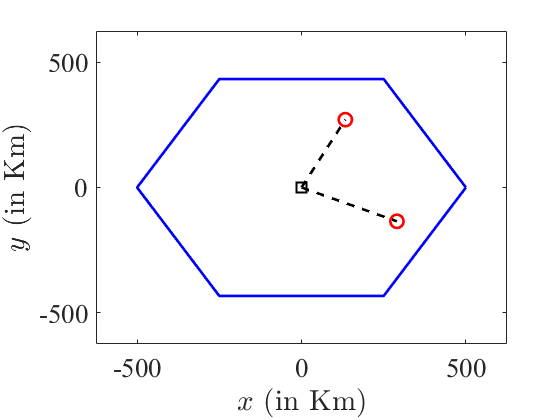

figure;

plot(x_cell,y_cell,'-b','linewidth',linewidth);
hold on;
plot(0,0,'sk','linewidth',linewidth,'markersize',markersize);
plot(x_user, y_user,'or','linewidth',linewidth,'markersize',markersize);
for k = 1:K
    plot([0 x_user(k)],[0 y_user(k)],'--k','linewidth',linewidth)
end
xlabel('$x$ (in Km)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
ylabel('$y$ (in Km)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');

set(gca,'fontname',fontname,'fontsize',fontsize);
xlim([-1.25*R 1.25*R]);
ylim([-1.25*R 1.25*R]);

## Sparse Multipath Channel

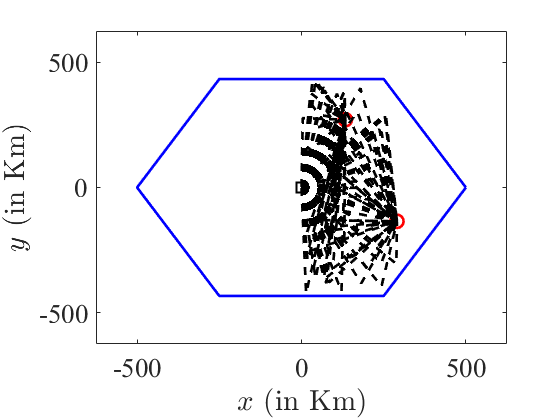

figure;

plot(x_cell,y_cell,'-b','linewidth',linewidth);
hold on;
plot(0,0,'sk','linewidth',linewidth,'markersize',markersize);
plot(x_user, y_user,'or','linewidth',linewidth,'markersize',markersize);
for k = 1:K
    for n = 1:N
        plot([0 x_object(k,n) x_user(k)],[0 y_object(k,n) y_user(k)],'--k','linewidth',linewidth)
    end
end
xlabel('$x$ (in Km)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
ylabel('$y$ (in Km)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');

set(gca,'fontname',fontname,'fontsize',fontsize);
xlim([-1.25*R 1.25*R]);
ylim([-1.25*R 1.25*R]);

# Generating Channel Matrices

## Large-scale Fading Calculation

The large-scale coefficient is independent of the small-scale effects and depend only the distances of BS and users

% aux_z = randn(K,1);
% z = exp(sigma_shadow_fad/sqrt(var(aux_z))*aux_z);

z         = lognrnd(mu_shadow_fad,sigma_shadow_fad,K,1);                % Shadow fading
path_loss = ((lambda/(4*pi*d_0))^2).*(d_0./r_bs_user).^delta;           % Path loss
beta      = z.*path_loss;                                               % Large-scale fading

## Idependent Rayleigh Fading (Rich Scattering Fading)

G_rich = randn(M,K) + 1i*randn(M,K);
G_rich = G_rich./abs(G_rich);

H_rich = G_rich*sqrt(diag(beta));                                       % Uplink channel matrix

norm(G_rich(:,1),2)^2

ans = 500.0000

var(G_rich(:,1))

ans = 0.9974

norm(H_rich(:,1),2)^2

ans = 1.3709e-05

od_rich = orthogonalityDeficiency(H_rich);                              % Orthogonality deficiency calculation

## Uniformly Random LoS Fading

steering_vector_ur_los = steeringVector(M,theta_user,d,lambda);

g_ur_los = randn(1,K) + 1i*randn(1,K);
g_ur_los = g_ur_los./abs(g_ur_los);

G_ur_los = repmat(g_ur_los,M,1);

H_ur_los = G_ur_los.*steering_vector_ur_los*sqrt(diag(beta));            % Uplink channel matrix

od_ur_los = orthogonalityDeficiency(H_ur_los);                           % Orthogonality deficiency calculation

## Sparse Multipath Fading

G_sm = zeros(N,K);
H_sm = zeros(M,K);

for k = 1:K
    steering_vector_sm = steeringVector(M,theta_object(k,:)',d,lambda);
    
    G_sm(:,k) = randn(N,1) + 1i*randn(N,1);
    G_sm(:,k) = G_sm(:,k)./abs(G_sm(:,k));
    
    H_sm(:,k) = sqrt(beta(k))*steering_vector_sm*G_sm(:,k);
end

od_sm = orthogonalityDeficiency(H_sm);                                   % Orthogonality deficiency calculation

disp(['Orthogonality Deficiency for Rich Sacattering Fading: ' num2str(od_rich)   newline ...
      'Orthogonality Deficiency for UR-LoS Fading:           ' num2str(od_ur_los) newline ...
      'Orthogonality Deficiency for Sparse Multipath:        ' num2str(od_sm)]);

Orthogonality Deficiency for Rich Sacattering Fading: 0.00055751
Orthogonality Deficiency for UR-LoS Fading:           2.8918e-06
Orthogonality Deficiency for Sparse Multipath:        0.00058536
